% 随机选取Boat图像8000对水平、垂直、对角线方向的像素
% After simplfiy
P = Imreadforgary(imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena512.bmp"));
C = Imreadforgary(imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena512.bmp"));
C = double(C);
[CICS,DI,RI]=VMIE(P,C);

历时 0.822533 秒。
历时 5.595152 秒。


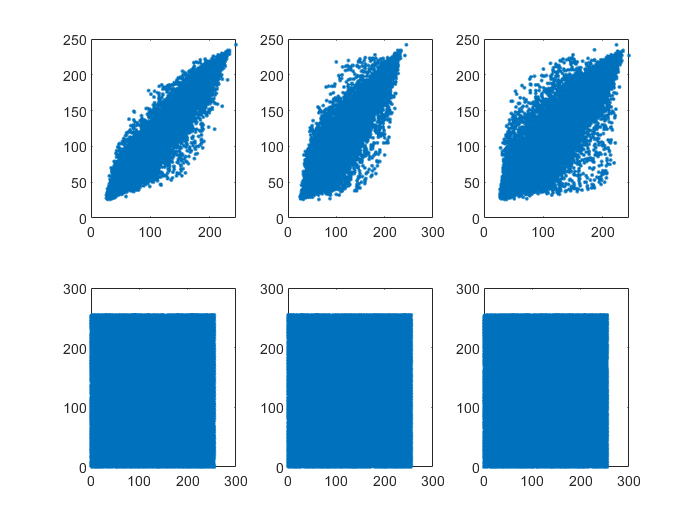



H=RandomSelect(P,100000,"horizontal");
V=RandomSelect(P,100000,"vertical");
D=RandomSelect(P,100000,"diagonal");


H1=RandomSelect(DI,100000,"horizontal");
V1=RandomSelect(DI,100000,"vertical");
D1=RandomSelect(DI,100000,"diagonal");

figure;
subplot(2,3,1);plot(H(1,:),H(2,:),'.');subplot(2,3,2);plot(V(1,:),V(2,:),'.');subplot(2,3,3);plot(D(1,:),D(2,:),'.');
subplot(2,3,4);plot(H1(1,:),H1(2,:),'.');subplot(2,3,5);plot(V1(1,:),V1(2,:),'.');subplot(2,3,6);plot(D1(1,:),D1(2,:),'.');

coefficient_of_association (H(1,:),H(2,:))

ans = 0.9850

coefficient_of_association (V(1,:),V(2,:))

ans = 0.9722

coefficient_of_association (D(1,:),D(2,:))

ans = 0.9598

coefficient_of_association (V1(1,:),V1(2,:))

ans = 0.0087

coefficient_of_association (H1(1,:),H1(2,:))

ans = -0.0021

coefficient_of_association (D1(1,:),D1(2,:))

ans = 0.0033